clear; clc;

% Shoulder to knee distance
L3 = 99.116E-3;

% Knee to ground distance
L4 = 104E-3;

% Spine top plane to shoulder
d2 = -31.75E-3;

% Shoulder motor axis to center of leg
d3= 64.008E-3;

center_to_spine_front = 107.442E-3;

x1 = 76.454E-3;
y1 = 107.442E-3;

x2 = 76.454E-3;
y2 = 107.188E-3;

L1__rear = sqrt(x2^2 + y2^2)

L1__rear = 0.1317


L1_front = sqrt(x1^2 + y1^2)

L1_front = 0.1319


Links.L1 = L1_front;
Links.L3 = L3;
Links.L4 = L4;
Links.d2 = d2;
Links.d3 = d3;


alpha = [0 0 pi/2 0 0]

alpha =          0         0    1.5708         0         0


a = [0 L1_front 0 L3 L4]

a =          0    0.1319         0    0.0991    0.1040


d = [0 d2 d3 0 0]

d =          0   -0.0318    0.0640         0         0



Lstd(1) = Link("revolute", 'a', a(1), 'd', d(1), 'alpha', alpha(1), 'modified');
Lstd(2) = Link("revolute", 'a', a(2), 'd', d(2), 'alpha', alpha(2), 'modified');
Lstd(3) = Link("revolute", 'a', a(3), 'd', d(3), 'alpha', alpha(3), 'modified');
Lstd(4) = Link("revolute", 'a', a(4), 'd', d(4), 'alpha', alpha(4), 'modified');
Lstd(5) = Link("revolute", 'a', a(5), 'd', d(5), 'alpha', alpha(5), 'modified');

std  = SerialLink(Lstd, 'name', 'boelt standard');


[off_fl, off_fr, off_bl, off_br] = offsets(x1, y1, x2, y2);
Lfl(1) = Link("revolute", 'a', a(1), 'd', d(1), 'alpha', alpha(1), 'offset', off_fl.t1, 'modified');
Lfl(2) = Link("revolute", 'a', a(2), 'd', d(2), 'alpha', alpha(2), 'offset', off_fl.t2, 'modified');
Lfl(3) = Link("revolute", 'a', a(3), 'd', -d(3), 'alpha', alpha(3), 'offset', off_fl.t3', 'modified');
Lfl(4) = Link("revolute", 'a', a(4), 'd', d(4), 'alpha', alpha(4), 'modified');
Lfl(5) = Link("revolute", 'a', a(5), 'd', d(5), 'alpha', alpha(5), 'modified');

fl = SerialLink(Lfl, 'name', 'boelt_fl');

Lfr(1) = Link("revolute", 'a', a(1), 'd', d(1), 'alpha', alpha(1), 'offset', off_fr.t1, 'modified');
Lfr(2) = Link("revolute", 'a', a(2), 'd', d(2), 'alpha', alpha(2), 'offset', off_fr.t2, 'modified');
Lfr(3) = Link("revolute", 'a', a(3), 'd', d(3), 'alpha', alpha(3), 'offset', off_fr.t3, 'modified');
Lfr(4) = Link("revolute", 'a', a(4), 'd', d(4), 'alpha', alpha(4), 'modified');
Lfr(5) = Link("revolute", 'a', a(5), 'd', d(5), 'alpha', alpha(5), 'modified');

fr = SerialLink(Lfr, 'name', 'boelt_fr');

Lbr(1) = Link("revolute", 'a', a(1), 'd', d(1), 'alpha', alpha(1), 'offset', off_br.t1, 'modified');
Lbr(2) = Link("revolute", 'a', a(2), 'd', d(2), 'alpha', alpha(2), 'offset', off_br.t2, 'modified');
Lbr(3) = Link("revolute", 'a', a(3), 'd', d(3), 'alpha', alpha(3), 'offset', off_br.t3, 'modified');
Lbr(4) = Link("revolute", 'a', a(4), 'd', d(4), 'alpha', alpha(4), 'modified');
Lbr(5) = Link("revolute", 'a', a(5), 'd', d(5), 'alpha', alpha(5), 'modified');

br = SerialLink(Lbr, 'name', 'boelt_br');

Lbl(1) = Link("revolute", 'a', a(1), 'd', d(1), 'alpha', alpha(1), 'offset', off_bl.t1, 'modified');
Lbl(2) = Link("revolute", 'a', a(2), 'd', d(2), 'alpha', alpha(2), 'offset', off_bl.t2, 'modified');
Lbl(3) = Link("revolute", 'a', a(3), 'd', -d(3), 'alpha', alpha(3), 'offset', off_bl.t3, 'modified');
Lbl(4) = Link("revolute", 'a', a(4), 'd', d(4), 'alpha', alpha(4), 'modified');
Lbl(5) = Link("revolute", 'a', a(5), 'd', d(5), 'alpha', alpha(5), 'modified');

bl = SerialLink(Lbl, 'name', 'boelt_bl');

figure(1)
clf()
q = [off_fr.t1, off_fr.t2, off_fr.t3, 0, 0]

q =     0.6185    0.9523   -1.5708         0         0


% std.plot(q)
% hold on
q = [0 0 pi/4 -pi/16 0]

q =          0         0    0.7854   -0.1963         0


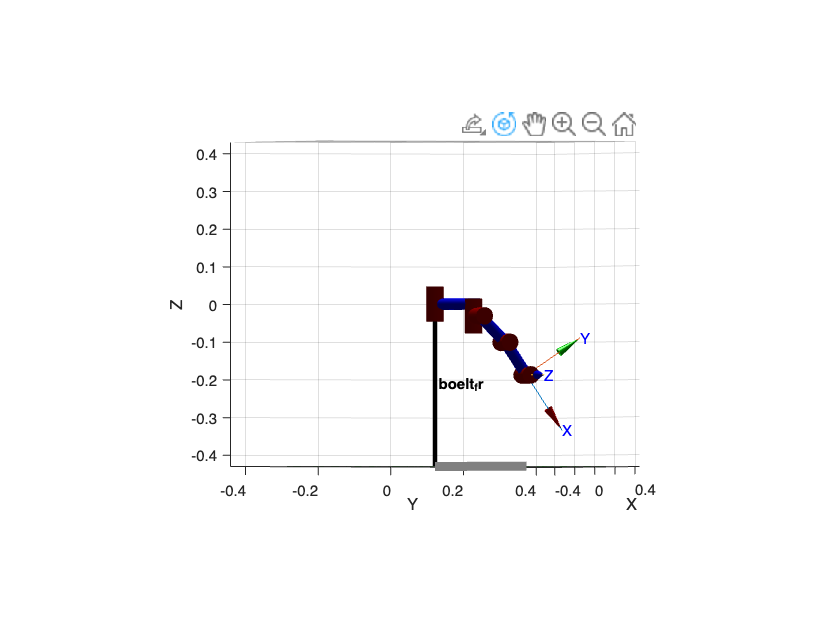

fr.plot(q)

fr.fkine(q)

 

ans = 
         0         0         1    0.1714
    0.5556    0.8315         0    0.2043
   -0.8315    0.5556         0   -0.1883
         0         0         0         1




[q2,q3,q4] = IK(Links, 0.1714, 0.06, -0.1883, off_fr.t1, off_fr);

g = 2.6434e-04

q2

q2 = 0.4518

off_fr.t2

ans = 0.9523


std.fkine([off_fr.t1, q2, q3, q4, 0])

 

ans = 
    0.3335    0.3451    0.8773    0.1714
    0.6097    0.6308   -0.4799      0.06
   -0.7191    0.6950         0   -0.1883
         0         0         0         1


std.plot([off_fr.t1, q2, q3, q4, 0])
[off_fr.t1, q2, q3, q4, 0]*180/pi

ans =    35.4350   25.8857 -124.4138   78.4374         0


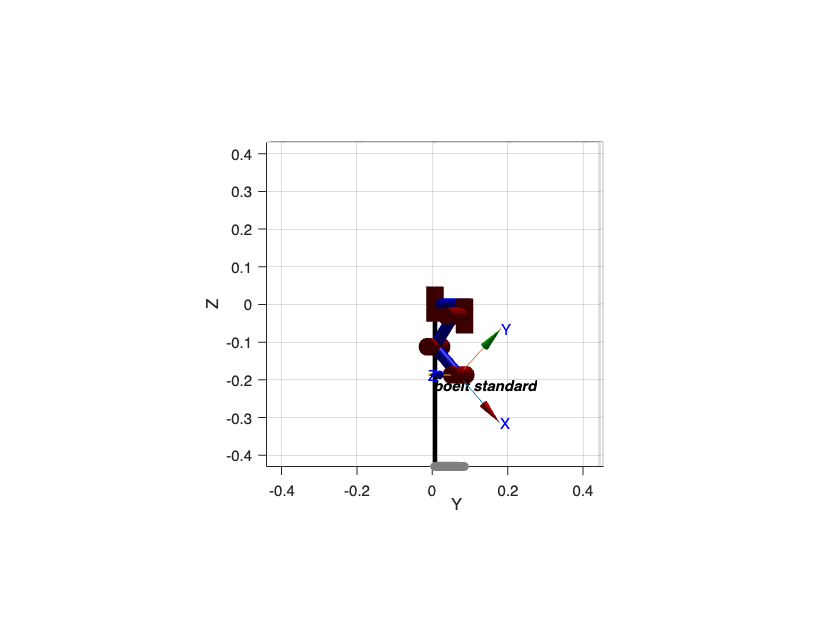


view([89.08 -0.12])

% % 
% [off_fr.t1 off_fr.t2 off_fr.t3 pi/24]








